# image_analysis.mlx

## First part - image analysis and processing using two dimensional DTFT

### section #4

Finding the two-dimensional transformation of x(n,m) according to the methods we proved in the first section and the third section

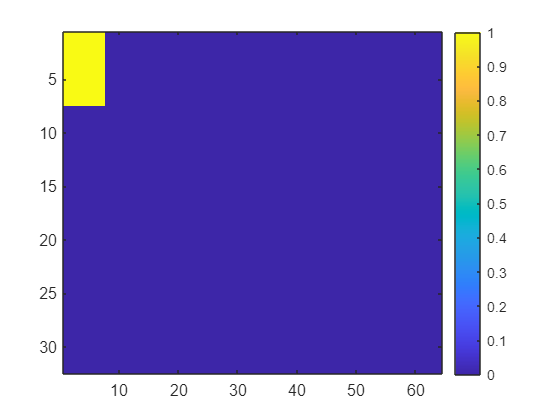

N = 32;
M = 64;
b1 = 7;
b2 = 7;

matrix = zeros(N, M);
matrix(1:b1, 1:b2) = 1;
figure
imagesc(matrix);
colorbar()


figure
imagesc(abs(fft_2D(matrix)));

'fft_2D' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\05ita\OneDrive - Bar-Ilan University - Students\לימודים\שנה ג\סמסטר ב\עיבוד דיגיטלי של אותות 1\MATLAB DSP ITAY
    MATAN

Change the MATLAB current folder or add its folder to the MATLAB path.

colorbar()

y = zeros(N,1);
y(1:b1) = 1;
Y = fft(y);

z = zeros(1,M);
z(1:b2) = 1;
Z = fft(z);

X = Y*Z;
figure
imagesc(abs(X));
colorbar()

[y_1,y_2,y_3,h]=img_gen('MATAN','ITAY');
h_0 = h(:,1);
imgs = {y_1,y_2,y_3,h};
names = {'y_1[n,m]','y_2[n,m]','y_3[n,m] - noised_image','h[n,m] - imp_resp_image'};
for i = 1:size(imgs,2)
    figure
    fprintf(names{i});
    imshow(imgs{i});
end

### section #5

h_0_zp = [h_0; zeros(size(h_0,1),1)];
H_0 = fft(h_0_zp);
% omega = 0
H_0(1)
% omega = 2pi/6
H_0(2)
% omega = 2*2pi/6
H_0(3)
% omega = 4*2pi/6
H_0(5)

### section #6

w = zeros(32,1);
w([1,30]) = 1;
W = fft(w);
h_0_zp32 = [h_0; zeros(29,1)];
H_0_zp32 = fft(h_0_zp32);
Mult = W.*H_0_zp32;
Conv = ifft(Mult);
figure
stem(0:31,Conv);


### section #7

Y_1 = fft_2D(y_1);
padSize = [125, 123];
h_zp = padarray(h, padSize, 0, 'post');
H = fft_2D(h_zp);
X_1 = Y_1./H;
x_1 = ifft_2D(X_1);
figure
imshow(real(x_1));

Y_2 = fft_2D(y_2);
padSize = [67, 165];
h_zp = padarray(h, padSize, 0, 'post');
H = fft_2D(h_zp);
X_2 = Y_2./H;
x_2 = ifft_2D(X_2);
figure
imshow(real(x_2));
